%Ioriginal = imread('originalimage.jpg')
%imshow(Ioriginal)
% = im2bw(Ioriginal, .01);
%imshow(I)

%I1 = imread('compressedimage.jpg')
%imshow(I1)
%I2 = im2bw(I1, .01);
%imshow(I2)

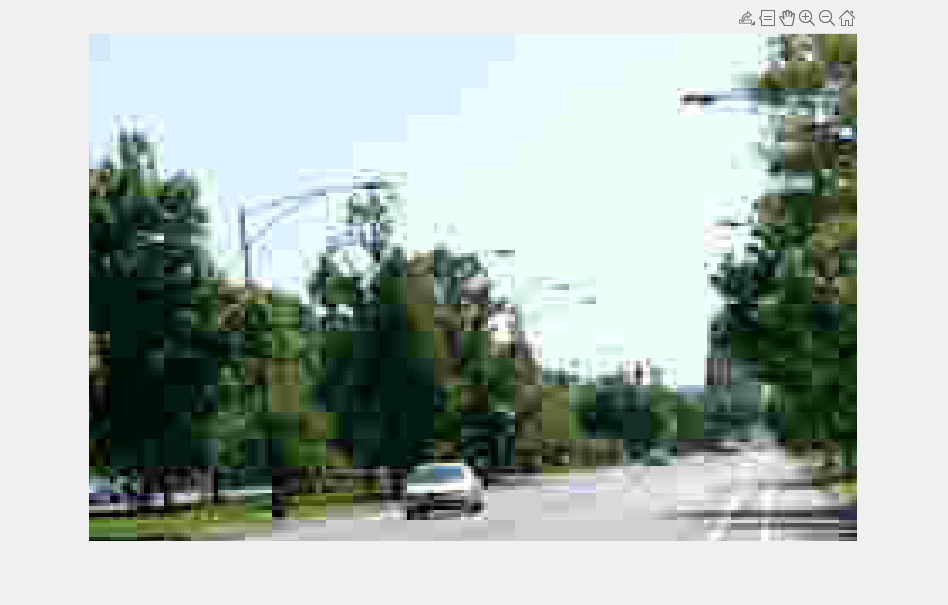

Icrop1 = 7×8×3 uint8 array
Icrop1(:,:,1) =

   223   223   223   223   223   223   223   233
   223   223   223   223   223   223   223   233
   223   223   223   223   223   223   223   233
   223   223   223   223   223   223   223   233
   223   223   223   223   223   223   223   233
   223   223   223   223   223   223   223   233
   223   223   223   223   223   223   223   233


Icrop1(:,:,2) =

   242   242   242   242   242   242   242   252
   242   242   242   242   242   242   242   252
   242   242   242   242   242   242   242   252
   242   242   242   242   242   242   242   252
   242   242   242   242   242   242   242   252
   242   242   242   242   242   242   242   252
   242   242   242   242   242   242   242   252


Icrop1(:,:,3) =

   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255
   255   255   255   255   255   255

%MAIN DETECTOR TEST
Icrop = imread('compressedimage.jpg');
%choose section to search block boundry TESTING ONLY
Icrop1= imcrop(Icrop)

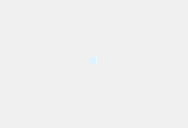

%show crop
imshow(Icrop1)

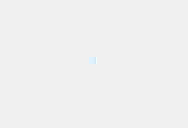

%sharpen to increase block boundry visibility
newim50col=imsharpen(Icrop1, 'Radius',2,'Amount',3);
imshow(newim50col)

BWIcrop1=im2gray(newim50col)

BWIcrop1 = 7×8 uint8 matrix
   238   238   238   237   236   232   227   250
   238   238   238   237   236   232   227   250
   238   238   238   237   236   232   227   250
   238   238   238   237   236   232   227   250
   238   238   238   237   236   232   227   250
   238   238   238   237   236   232   227   250
   238   238   238   237   236   232   227   250


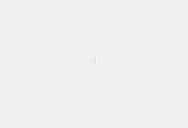

imshow(BWIcrop1)

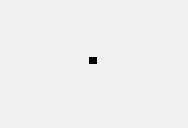

%run canny edge detector to find block boundry
edgeim = edge(BWIcrop1,'canny');
imshow(edgeim)


Ioriginal = imread('originalimage.jpg')

Ioriginal = 683×1024×3 uint8 array
Ioriginal(:,:,1) =

   210   210   210   210   211   211   211   211   211   211   211   211   211   211   211   211   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   214   214   214   214   215   215   215   215   212   212   213   213   214   214   215   215   214   214   214   214   216   216   216   216   214   214   214   214   214   214   214   214   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   216   216   216   216   215   215   215   216   218   219   219   219   217   217   217   219   219   220   220   221   221   222   222   222   222   222   222   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   222   

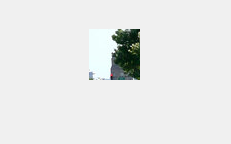

Icrop1= imcrop(Ioriginal,[246.5 90 50 50]);
imshow(Icrop1)

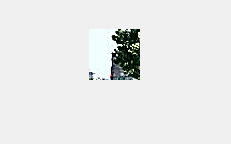

newim50col=imsharpen(Icrop1, 'Radius',2,'Amount',3);
imshow(newim50col)

BWIcrop1=im2gray(newim50col)

BWIcrop1 = 51×51 uint8 matrix
   250   250   250   250   250   250   250   251   247   247   251   250   250   250   250   250   250   251   253   239   248   247   253   253   252   253   254   253   251     4     5     5   250   252   253   253   252    53    46   251   251    74    10    22    14    71    94    41     9    10
   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   251   247   251   253   252   237   253   253   253   254   252   250    85    23   174   194   207   251   251    68   206   216   252   252   252    12    46    34    60    53    14     5     4
   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   250   251   252   234   251   251   253   253   253   252   121     2     4    56   170   195   204   105    68   148    64    10   113   134   183   148     7    42   105    14    36     6     4     4
   250   250   246   250   250   250   250   250   250   250   250 

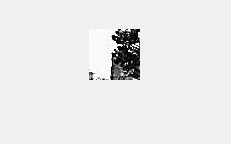

imshow(BWIcrop1)

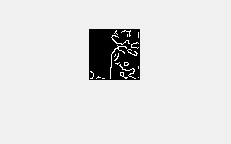

edgeim = edge(BWIcrop1,'canny');
imshow(edgeim)